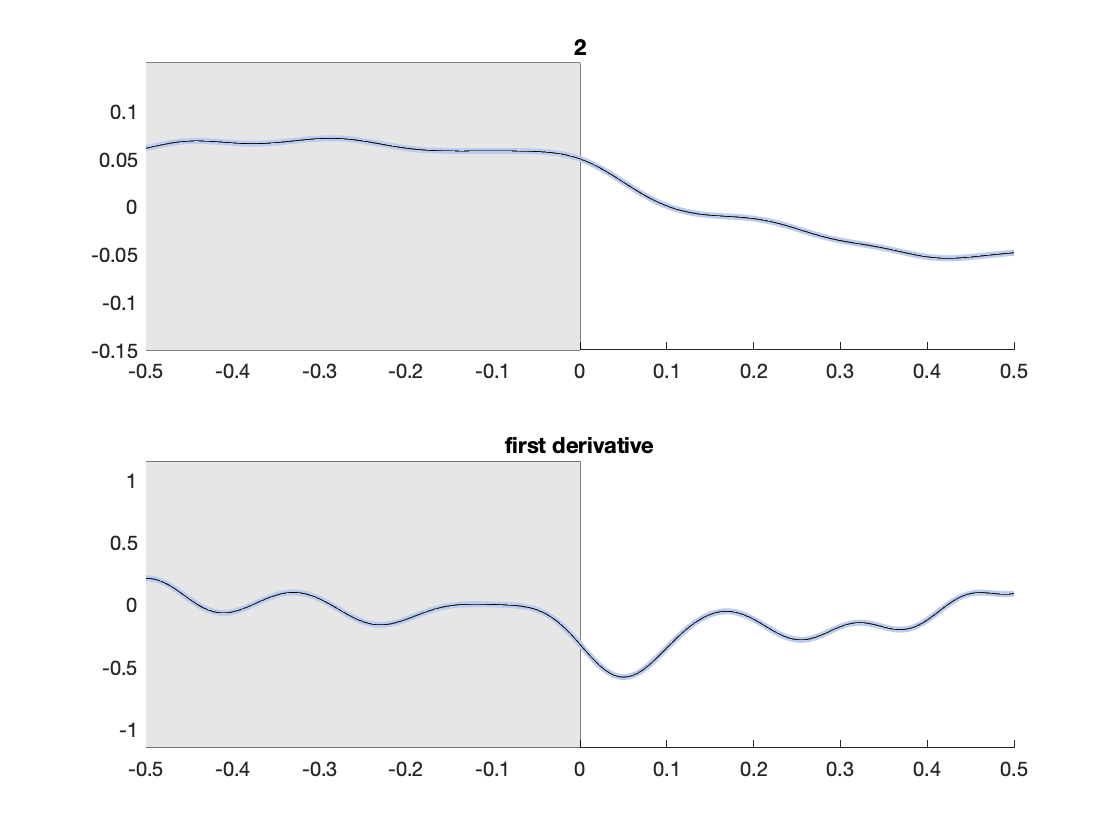

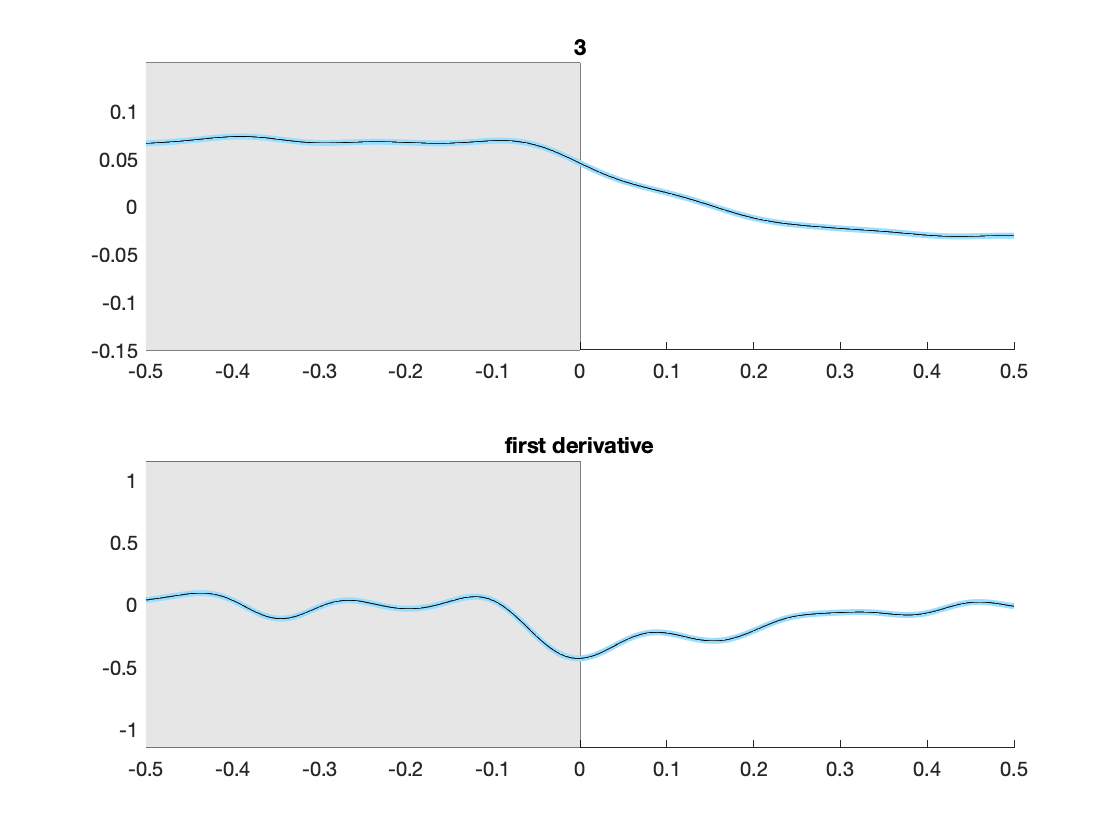

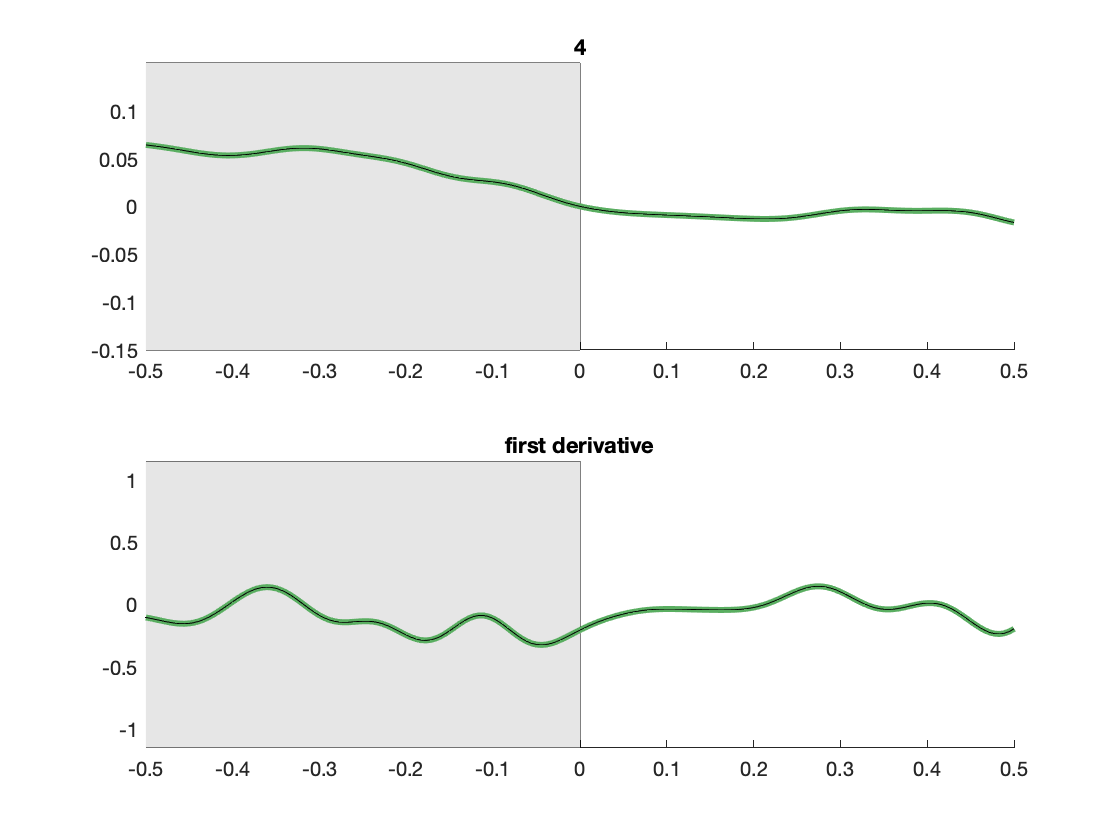

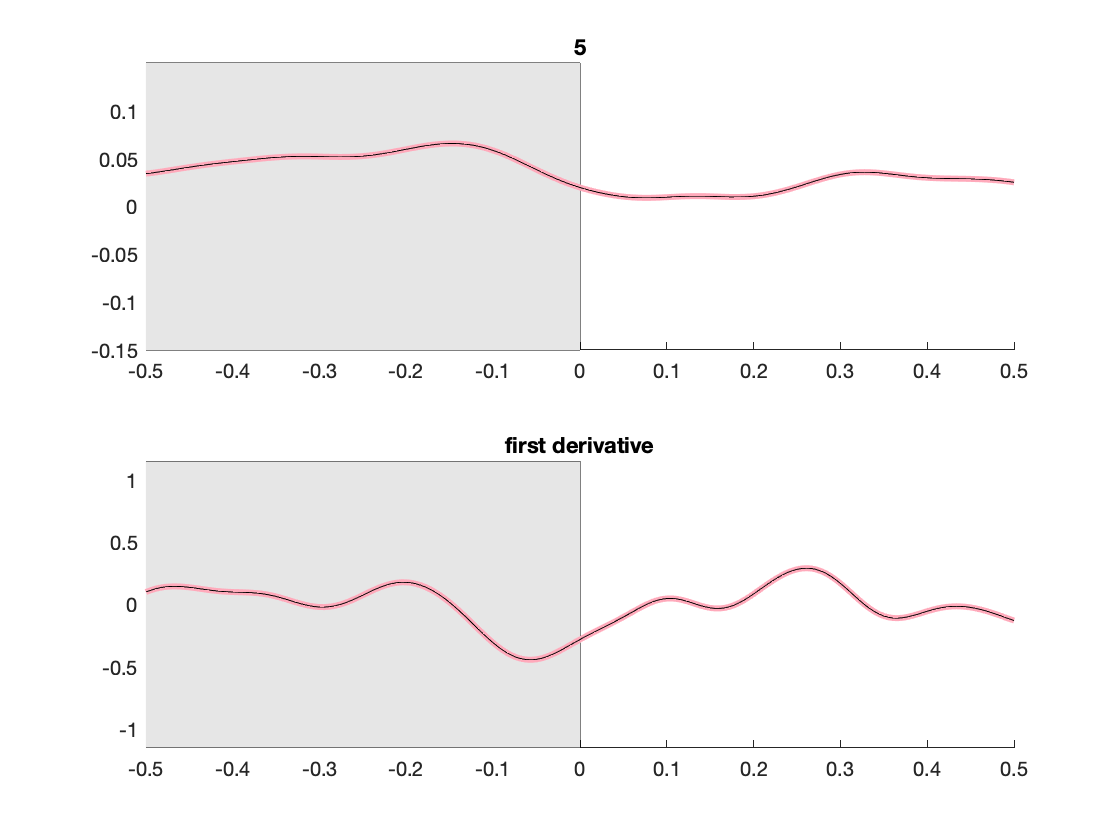

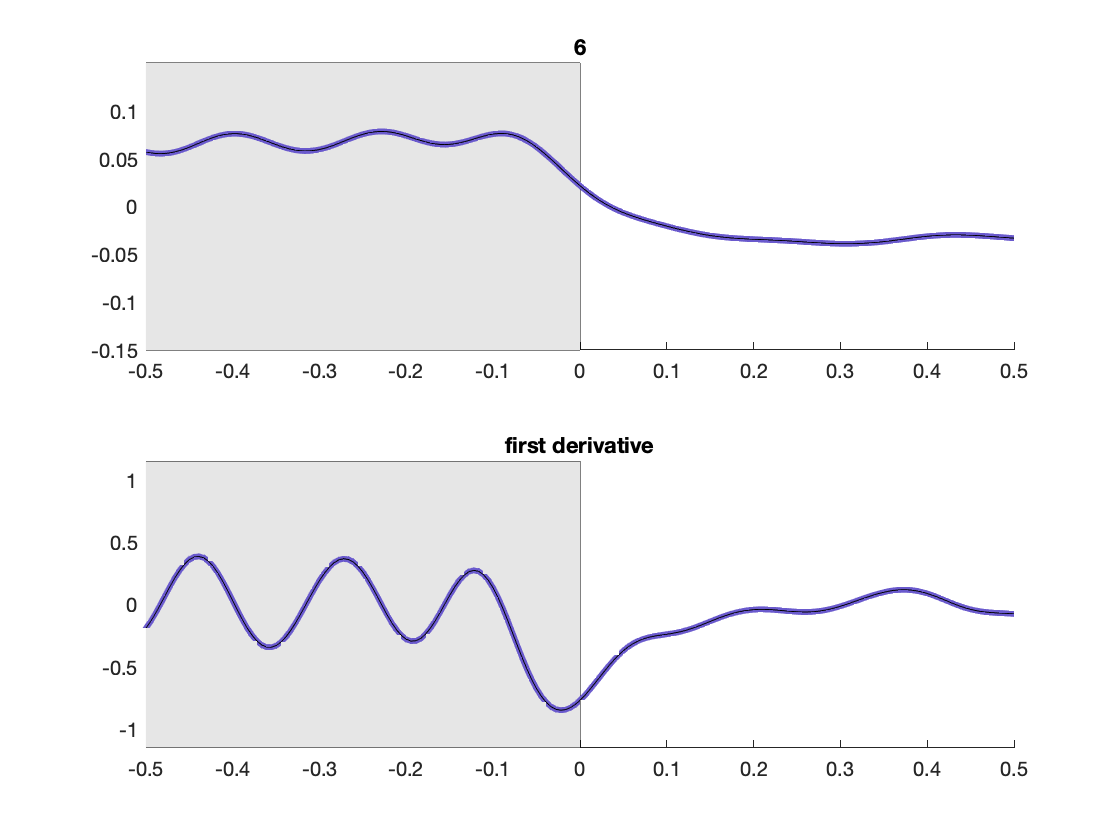

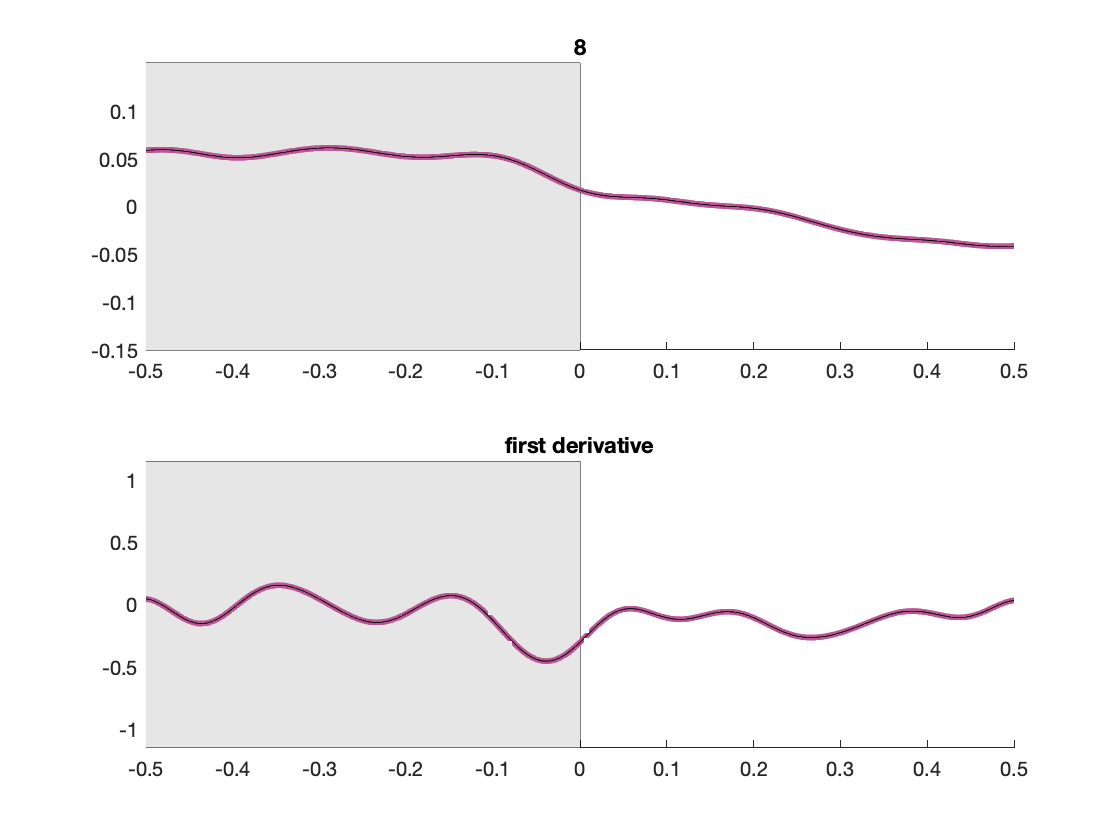

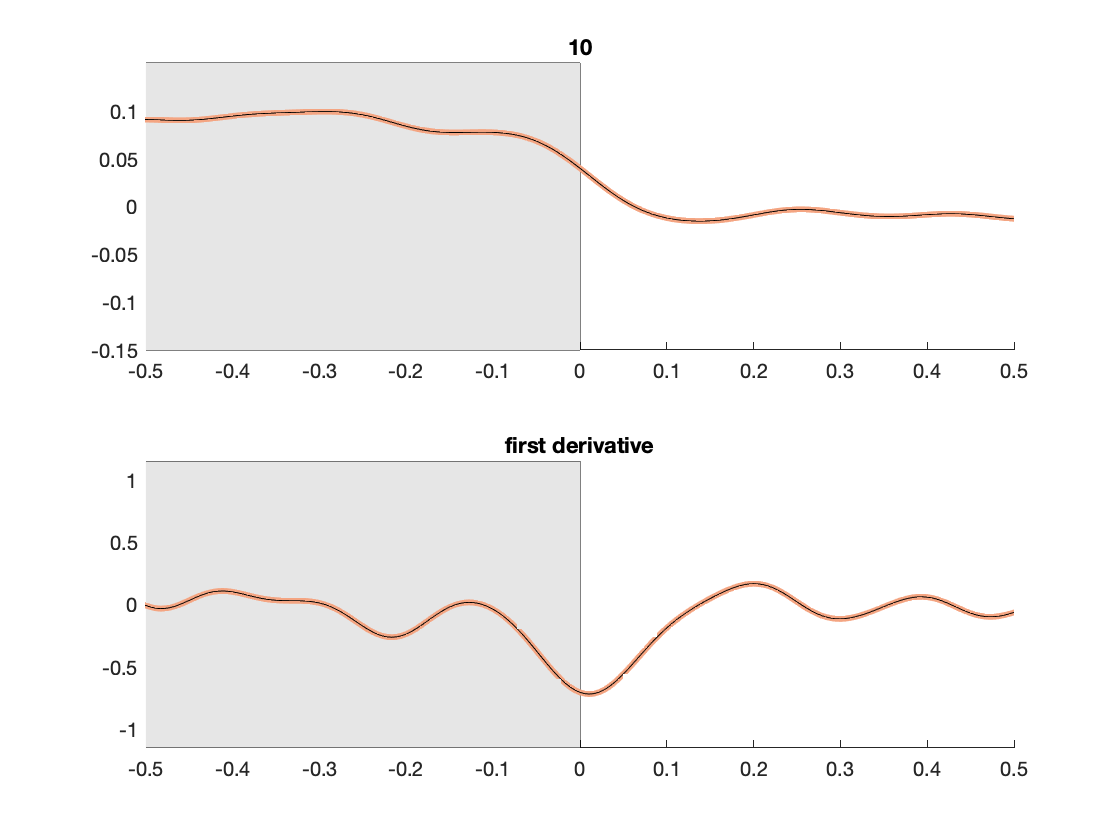

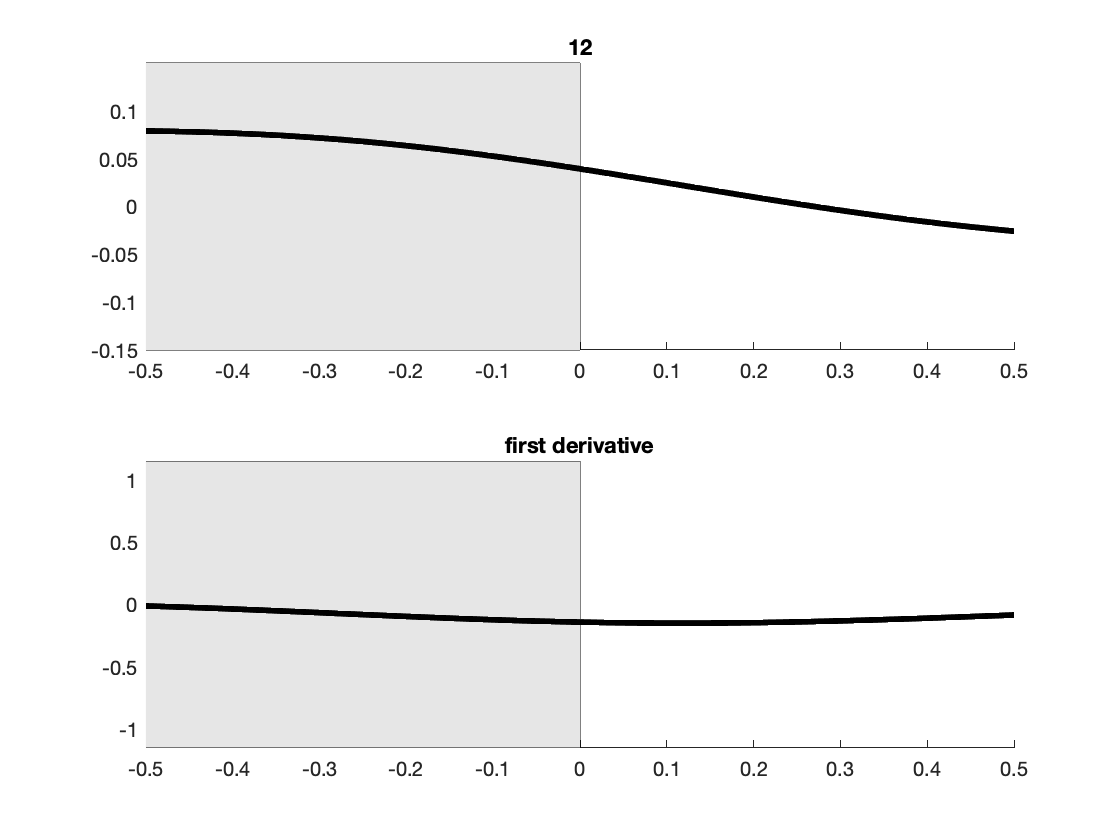


clrs = k_colormefriendly;

    

    for j = 1:length(dark)

  figure(j); clf; hold on; 

     ld(j,:) = dark(j).ld;
    ax(1) = subplot(211); title(num2str(ld(j))); hold on;
        ylim([-.15 .15]);
        xlim([-0.5 0.5]);
        a = ylim; fill([-ld(j) -ld(j) 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
        plot(dark(j).exp.hourtim-ld(j), dark(j).exp.meanofexperimentmeans, 'LineWidth', 3,'Color', clrs(j,:));
        plot(dark(j).exp.hourtim-ld(j), dark(j).exp.meanofexperimentmeans, 'LineWidth', .5,'Color', 'k');
        
    ax(2) = subplot(212); title('first derivative'); hold on;
        
        darkdy = gradient(dark(j).exp.meanofexperimentmeans)./gradient(dark(j).exp.hourtim);

          ylim([-1.15 1.15]);xlim([-0.5 0.5]);
          a = ylim; fill([-ld(j) -ld(j), 0 0 ], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

          plot(dark(j).exp.hourtim-ld(j), darkdy,'LineWidth', 3,'Color', clrs(j,:));
          plot(dark(j).exp.hourtim-ld(j), darkdy,'LineWidth', .5,'Color', 'k');

    linkaxes(ax,'x');    
    end

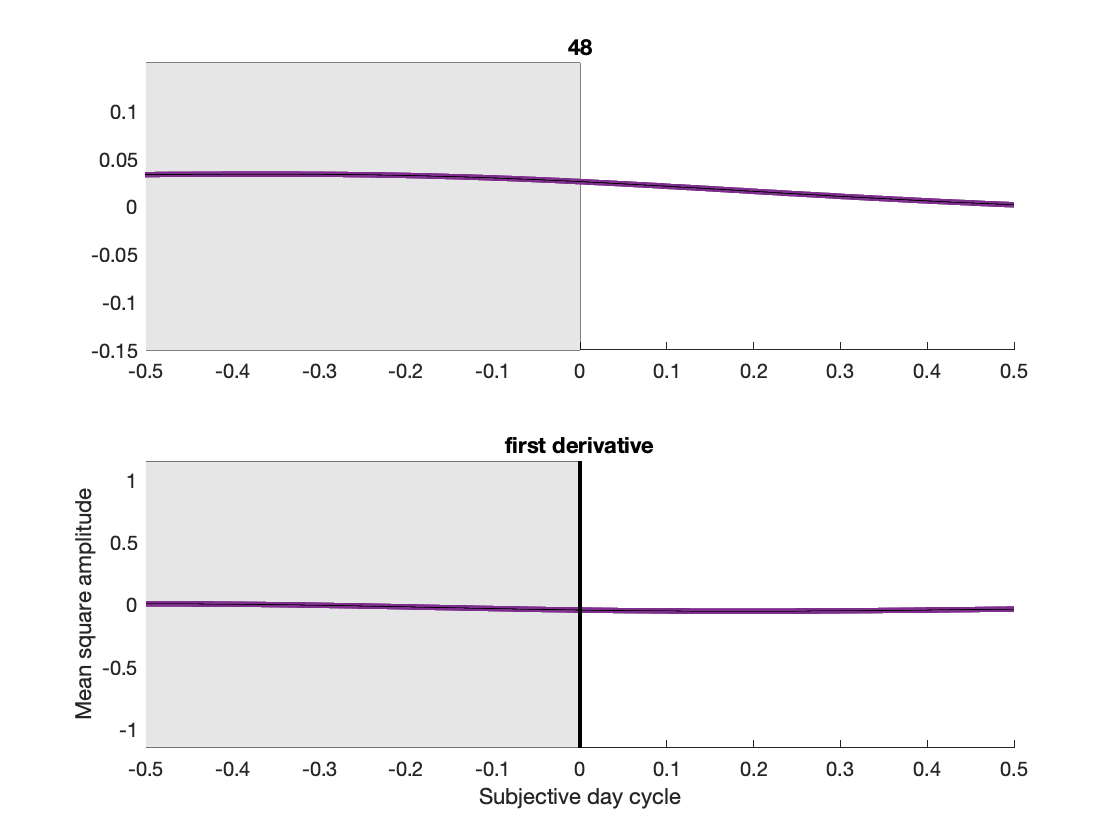

       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');